# MD Simulation using Psi4    

### Introduction

In this example, we show how [Psi4](https://psicode.org/), an open-source suite of *ab initio* quantum chemistry programs, is used for molecular dynamics (MD) simulations. This [Psi-MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) workflow starts with a single molecular structure input, rotates it around a C-C bond, and calculates the molecular energy at the desired theory level at each time step.  The output of the Psi4 computations is then processed in MATLAB to extract data and to build a single .mat file for further analysis.  

### Setting up the conda environment

Psi4 can be installed from this [source](https://psicode.org/installs/v17/). This example is using conda environment setup for this software. It is always a good practice to clear the MATLAB workspace first. We then activate the Psi4 conda environment.   

clear;
clc;
close all;
warning('off','all')

pyenv("Version","C:\Users\...\AppData\Local\Continuum\anaconda3\envs\p4env\python.exe");
pyrunfile("echo_env.py")

p4env


### Input molecule in sdf format and convert to xyz

We use [penicillamine](https://pubchem.ncbi.nlm.nih.gov/compound/Penicillamine) for this example. Penicillamine is a FDA approved chelating agent used to decrease copper stores in Wilson disease. The initial configuration is the distorted molecular geometry due to 60 degrees rotation around the C5-C6 single bond. The final optimized geometry is also visualized here using [Molviewer](https://www.mathworks.com/help/bioinfo/ref/molviewer.html) for comparison. '*Convert_sdf_to_xyz*' is a MATLAB function that converts the Structure-Data File (sdf) format to XYZ format for further processing.

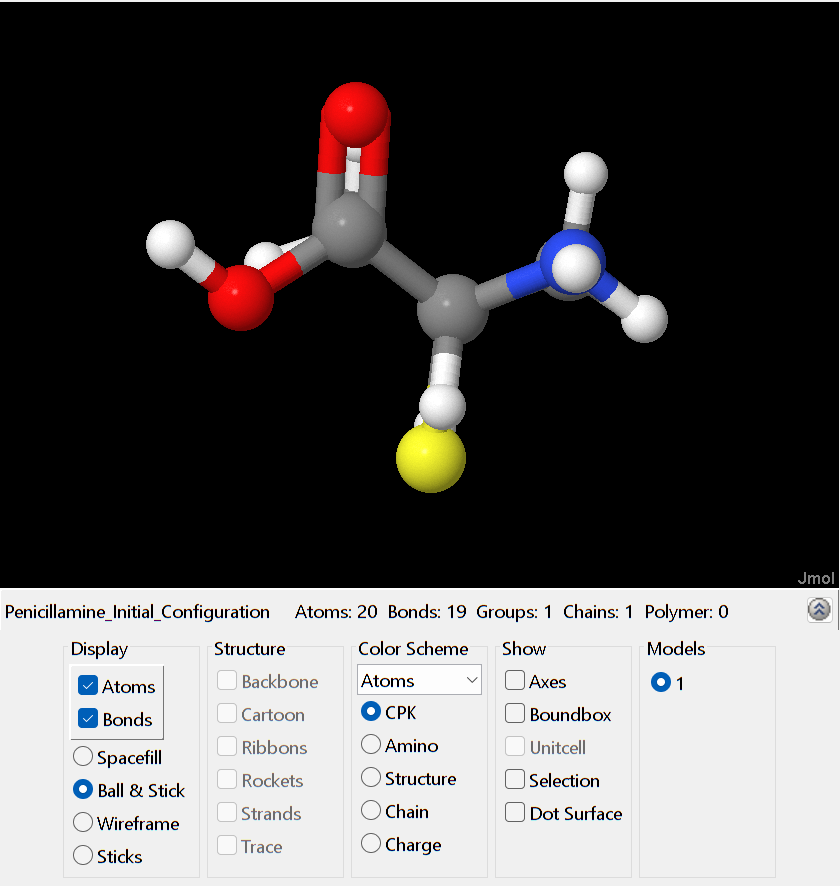

filename = sprintf ('Penicillamine_Initial_Config.sdf');
[numatoms] = numatoms_from_sdf(filename);
figure(1), molviewer(filename)

Convert_sdf_to_xyz(filename);

Penicillamine_Initial_Config.sdf
1 molecule converted 


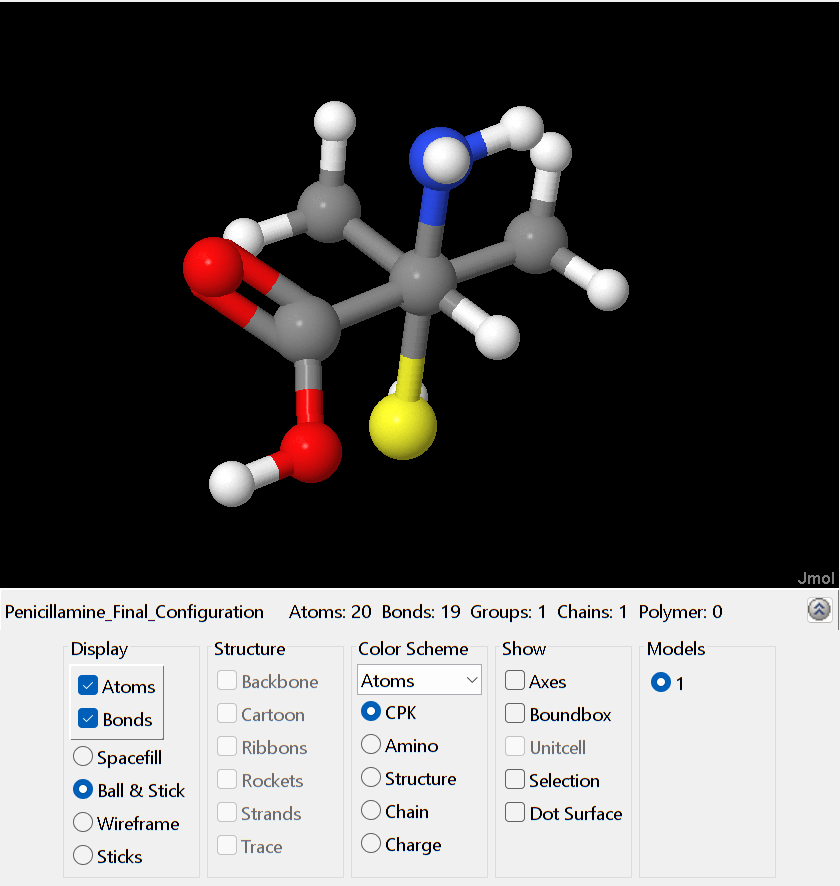

finalconfig = sprintf ('Penicillamine_Final_Config.sdf');
figure(2), molviewer(finalconfig);

### Set up the MD simulations

Refer to Psi4 documentation for [Single-Point Energy](https://psicode.org/psi4manual/master/energy.html) setup. In this example Hartree–Fock (HF) self consistent field (SCF) theory level is used with cc-pvtz [basis set](https://psicode.org/psi4manual/master/basissets.html). The MD simulations are done when the molecule is rotated around C5-C6 single bond (z-axis). Molviewer is used to identify the indices of the rotating atoms '*idx*'. The generated xyz and Python input files can be stored in dedicated folders, for which the paths should be given.

basis = 'cc-pvtz';
theory_level = 'hf';
idx = [ 2 3 4 6 9 10 17 18 20 ];  % which atoms should rotate: Use a visualization tool
tot_steps = 60;
theta_end = 60;  % Rotate around central C-C bond
theta_step = theta_end./tot_steps;

xyzpath = 'C:\\Users\\...\\xyz_input_files\\';
pypath = 'C:\\Users\\...\\psi4_py_files\\';

### Generate the MD configurations and running the Psi4 simulations

Since the C5-C6 bond is initialy set as the intermolecular z-axis, we can use MATLAB's built-in rotation matrix function, [rotz](https://www.mathworks.com/help/phased/ref/rotz.html), to generate the new configurations for this structural transformation. 

'*ZRotate_Molecule*' is the function that takes in the initial configuration saves the rotated geometry as xyz file in the xyzpath folder. 

'Psi4_py_input_builder' builds the python script to run the Psi4 calculations. The output is overwritten in the '*Psi4_Output.dat*' datafile for further processes.

'*Get_Atomic_Numbers*' extracts the atomic numbers and atomic symbols from the Psi4 output. "Get_Atomic_Geometries" and 'Get_Total_Energy' extracts the atomic coordinates and the computed energy at each time step, respectively.

All extracted variables can then be saved in one '*.mat*' data file for future work. 

for timestep = 1:tot_steps
    theta = timestep.*theta_step;
    [xyzfile] = ZRotate_Molecule(filename,xyzpath,numatoms,theta,idx);
    [pyfilename] = Psi4_py_input_builder(xyzfile,xyzpath,pypath,numatoms,basis,theory_level,theta);
    pyrunfile(pyfilename);
    psi4_output = 'Psi4_Output.dat';    
   
    [AtomicNums,AtomSymbols] = Get_Atomic_Numbers(psi4_output,numatoms);
    [GeomMat] = Get_Atomic_Geometries(psi4_output,numatoms);
     GeomMatrix(:,:,timestep) = GeomMat;
    [Eng_Total] = Get_Total_Energy(psi4_output);
     Engvec(timestep,1) = Eng_Total;
end

psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 
psi4_input_bottom.dat 
        1 file(s) copied. 
psi4_input_top.dat 



save('Psi4_output_data.mat',"AtomicNums","GeomMatrix","Engvec");

### Results

Figure (3) shows the total energy vs. the rotation angle. The [steric effect](https://www.sciencedirect.com/topics/chemistry/steric-effect) in the initial configuration explains the observation of the high starting energy during the MD simulation. This energy monotonically decreases when the conformational restriction is removed during the simulation, until the structure reaches its minimum energy.   

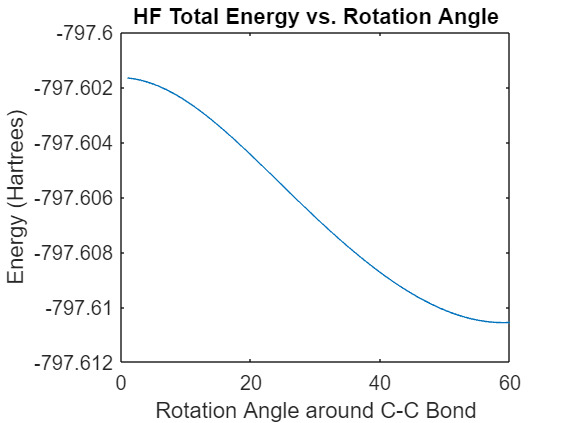

load('Psi4_output_data.mat');
angle = 1:tot_steps;
plot(angle,Engvec) 
xlabel('Rotation Angle around C-C Bond'), ylabel('Energy (Hartrees)')
title('HF Total Energy vs. Rotation Angle')

We can store the conformational structures during the simulation by calling the '*Trajcetory*' function. The generated XYZ file can be then viewed with a molecular visualization program like [VMD](https://www.ks.uiuc.edu/Research/vmd/). 

Trajectory(xyzpath);

VMD_path = '"C:\Program Files (x86)\University of Illinois\VMD\vmd.exe"';
trajname = 'trajectory.xyz';
cmd = [VMD_path ' ' trajname]; 
system(cmd);

Info) VMD for WIN32, version 1.9.3 (November 30, 2016) 
Info) http://www.ks.uiuc.edu/Research/vmd/                          
Info) Email questions and bug reports to vmd@ks.uiuc.edu            
Info) Please include this reference in published work using VMD:    
Info)    Humphrey, W., Dalke, A. and Schulten, K., `VMD - Visual    
Info)    Molecular Dynamics', J. Molec. Graphics 1996, 14.1, 33-38. 
Info) ------------------------------------------------------------- 
Info) Multithreading available, 8 CPUs detected. 
Info) Free system memory: 4095MB (100%) 
Warning) Detected a mismatch between CUDA runtime and GPU driver 
Warning) Check to make sure that GPU drivers are up to date. 
Info) No CUDA accelerator devices available. 
Info) OpenGL renderer: Intel(R) UHD Graphics 620 
Info)   Features: STENCIL MDE CVA MTX NPOT PP PS GLSL(OVFGS)  
Info)   Full GLSL rendering mode is available. 
Info)   Textures: 2-D (16384x16384), 3-D (1024x1024x1024), Multitexture (8) 
Info) No joysticks found.  